# MATLAB + Simulink Workflow for Adaptive Control and ROS2 Development

## Overview

This document outlines a recommended workflow for developing matrix-based controllers and adaptive algorithms using MATLAB, Simulink, and ROS 2.

The workflow follows this progression:

**MATLAB (.mlx/.m) → Simulink (.slx) → ROS 2 Deployment**

## Why Start in MATLAB / Live Script

For matrix-based controllers, MATLAB provides:

- Fast iteration with linear algebra tools (`eig();` svd`(); lqr(); `)

- Easy visulization and debugging

- No timing constraints

- Clear validation of mathematical correctness

### Example: prototype controller

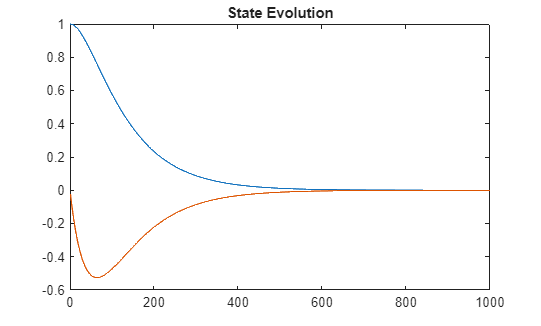

% Prototype adaptive update law
A = [0 1; -2 -3];
B = [0; 1];

Q = eye(2);
R = 1;

K = lqr(A,B,Q,R);

% simulate discrete-time update
Ts = 0.01;
x = [1;0];  % reference state?

for k= 1:1000
    u = -K*x;
    x = x + Ts*(A*x + B*u); % Euler discetization
    x_log(:,k) = x;
end

plot(x_log')
title('State Evolution')

## Important Transition: .mlx -> .m

live scripts are not ideal for integration or deploymnet.

Instead, convert your logic into clearn MATLAB functions:

function [x_next, u] = controllerStep(x, A, B, K, Ts)
%controllerStep One-step discrete update

u = -K*x;
x_next = x + Ts*(A*x + B*u);

end

Key properties:

- Explicit inputs/outpus

- No hidden state

- Code-generation friendly

## Integration into Simulink

Use a MATLAB function block to call your function:

function [x_next, u] = fcn(x, A, B, K, Ts)
%#code gen
[x_next, u] = controllerStep(x, A, B, K, Ts);
end

## Key Concept: Discrete-Time Update

Your controller becomes:


$$x_{k+1} = f(x_k, u_k, T_s)$$


Where:

- Ts = sample time

- Each execution = one timestep

MATLAB vs Simulink Mindset

Why this matters for ROS2

in ros 2 systems

messages may arrive asynchronoously

data may be delayed

rates may differ between nodes

by designing in discrete time, oyu can test:

one step delay effects

rate mismatches

communication latency

recommended workflow

phase1: matlab .mlx

phase2: maltlab functons .m

phase3: simulink multi-rate idea for sensors and actuators, but now can fix at one 

phase 4: simulink single rate (idea in the pdf file)

phase 5: back to multi-rate, actually actively change sensor and actuator and communications

phase 6: fixed step solver for global execution

then later for embedded ros deplymnet!!!